In this notebook, we show a simple demo on how to use the provided "processing_simulation.m" function to simulate the trajectory of the end-effecotr given a input command (x, y, z coordinates over time).

-------------------
Il y aura simulation Y/N: 1.
Trajectory dataset name is:  example_trajectory_pick_no_failure.
Trajectory: circles Y/N: 0 amount: 0.
Trajectory: lines Y/N: 0 amount: 0.
Trajectory: interpolation Y/N: 0 amount: 100.
Trajectory: realistic_trajs Y/N: 1 amount: 1.
Les erreures moteur seront : [,0]
Il y aura entrainement Y/N: 0.
Le modèle de robot simulé est : main3_armpi_fpv .
Le bras du robot pleinement étendu mesure: 0.280000 m.
Le nombre de points par trajecoire est: 1000 points.
Le speedcap est: 2.000000e-01.
-------------------
Le zero_amount dans realistic_traj: 0.
-------------------
Le average_smallest_motive_lenght dans realistic_traj: 50.
-------------------
Le stationary_error est: 20.
-------------------
Le stationary_error_timestap est: 100.
-------------------
Le joint1_damping est: 0.
Le joint1_damping est: 0.
Le damp_pince est: 1000.
Le modèle de robot est: robot_model.


La base est: robot_model/World/W.
La follower est: robot_model/gripper_base/F.
Les targetIDs sont: gripper_base.Translation.x.
Les targetIDs sont: gripper_base.Translation.y.
Les targetIDs sont: gripper_base.Translation.z.
Les outputIDs sont: j1.Rz.q.
Les outputIDs sont: j2.Rz.q.
Les outputIDs sont: j3.Rz.q.
Les outputIDs sont: j4.Rz.q.
Les outputIDs sont: j5.Rz.q.
Les guessesIDs sont: j1.Rz.q.
Les guessesIDs sont: j2.Rz.q.
Les guessesIDs sont: j3.Rz.q.
Les guessesIDs sont: j4.Rz.q.
Les guessesIDs sont: j5.Rz.q.
Les guesses sont : [3,3,3,3,3]
Le scale facotr est: 3.358490e-01.
The number of cells is:1


----------
Motor off is: 0
Progression is: 1
----------


----------------
----------------
----------------
----------------


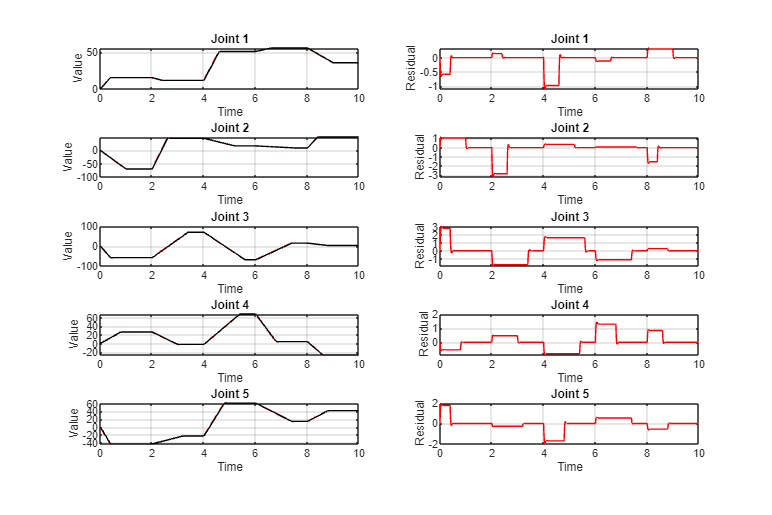

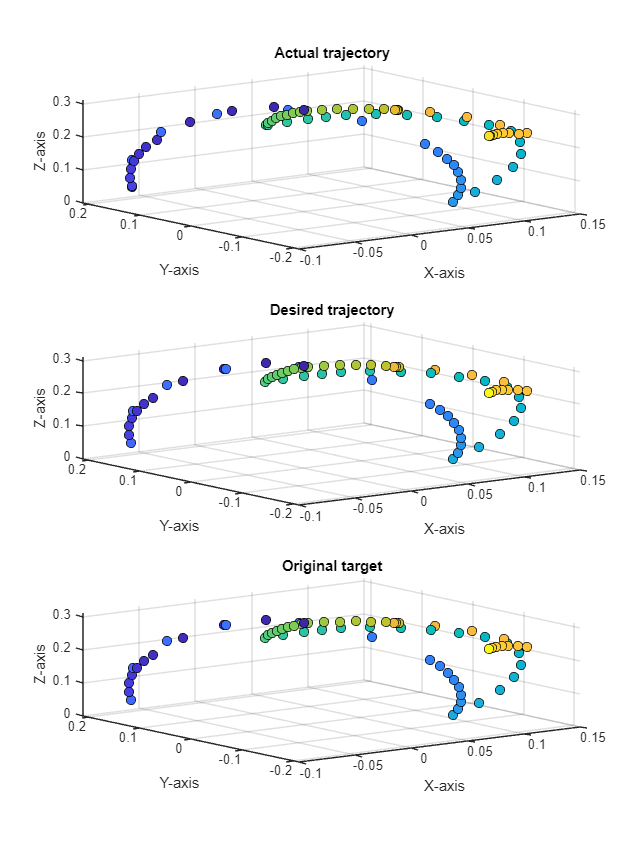

The final size of the dataset2 is [1000 6]The final size of the fulldataset is [1000 6]Dataset saved


clear; clc;
close all;

% processing_simulation(1, 'trajectory_dataset_name', 'example_trajectory_dataset_circles_1_no_failure', 'circles', 1, 'circle_number', 1, 'selection_erreures_moteur', [0],...
    % 'lines', 0, 'line_number', 0)
processing_simulation(1, 'trajectory_dataset_name', 'example_trajectory_pick_no_failure', 'circles', 0, 'circle_number', 0, ...
    'lines', 0, 'line_number', 0, 'realistic_trajs', 1, 'realistic_trajs_number', 1, 'selection_erreures_moteur', [0])

sim('robot_model_visualization.slx');